#### Phase 1 & Phase 2: Analysis

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s



time_delta=0.5

time_delta = 0.5000

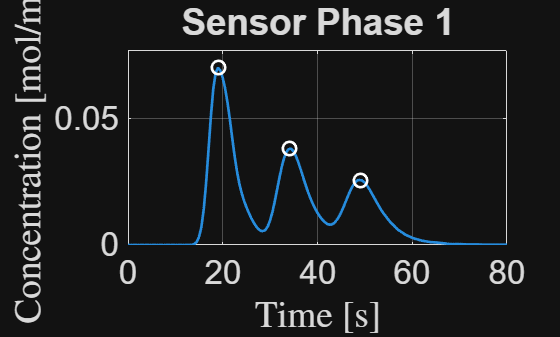


%Loading simulation results generated by COMSOL
% Specify the CSV file
csvFileName = 'c_CNN_Phase_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_CNN.Var1);
c_COMSOL_Sensor_Phase_1=(Table_c_Pipe_CNN.Var2);
h_COMSOL_CNN_Phase_1=gradient(c_COMSOL_Sensor_Phase_1,t_COMSOL);

%finding the peaks
%First peak
[~,t_peak_A_COMSOL]=max(h_COMSOL_CNN_Phase_1);
% t_peak_A_COMSOL=(t_peak_A_COMSOL-1)*time_delta;
%Second peak
x1=round((t_peak_A_COMSOL+tau_sample/time_delta/2));
x2=x1+(tau_sample)/time_delta;
[~,t_peak_B_COMSOL]=max(h_COMSOL_CNN_Phase_1(x1:x2));
t_peak_B_COMSOL=t_peak_B_COMSOL+x1-1;
% t_peak_B_COMSOL=(t_peak_B_COMSOL-1)*time_delta+(x1)*time_delta;
% %Third peak
x1=x2;
x2=x1+(tau_sample)/time_delta;
[~,t_peak_C_COMSOL]=max(h_COMSOL_CNN_Phase_1(x1:x2));
t_peak_C_COMSOL=t_peak_C_COMSOL+x1-2;
% t_peak_C_COMSOL=(t_peak_C_COMSOL-1)*time_delta+(x1-1)*time_delta;

t=0:time_delta:time_simul;
figure;

% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_CNN_Phase_1,'LineWidth',2,'MarkerIndices',1:ceil(length(h_COMSOL_CNN_Phase_1)/15):length(h_COMSOL_CNN_Phase_1)); grid on; hold on;
plot((t_peak_A_COMSOL-1)*time_delta,h_COMSOL_CNN_Phase_1((t_peak_A_COMSOL)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot((t_peak_B_COMSOL-1)*time_delta,h_COMSOL_CNN_Phase_1((t_peak_B_COMSOL)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot((t_peak_C_COMSOL)*time_delta,h_COMSOL_CNN_Phase_1((t_peak_C_COMSOL)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;% plot([x1 x1]*time_delta,[0 1])
% plot([x1 x1]*time_delta,[0 1])
% plot([x2 x2]*time_delta,[0 1])

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 1')
axis([0 t(end) 0 1.1*max(h_COMSOL_CNN_Phase_1)]);